# HW5 Gabe Colangelo

clear
close all 
warning off
clc

% Symbolic State and Input Vectors
x_sym   = sym('x',[6,1],'real');
u_sym   = sym('u',[3,1],'real');

% Numeric System Parameters
m1      = 0.5;
L1      = 0.5;
m2      = 0.75;
L2      = 0.75;
M       = 1.5;
g       = 9.81;


## Problem 2 - UIO Design

% Equilibrium State
xe      = zeros(6,1);

% Non-linear System
f       = DIPC([],x_sym, u_sym, m1, m2, M, L1, L2, g);
out     = x_sym(1:6);

% Solve for Equilibrium Input
fsol_opt= optimset('Display','off');
f_xe    = @(u)DIPC([],xe, u, m1, m2, M, L1, L2, g);
ue      = fsolve(f_xe,[0 0 0]',fsol_opt);


$$\dot{x} = Ax + B_1u_1 + B_2u_2 \\
y = Cx + D_1u_1 + D_2u_3$$


% Jacobian Matrices/ Linearized Model about Equilibrium Pair
A       = double(subs(jacobian(f,x_sym),[x_sym;u_sym],[xe;ue]))

A =          0         0         0    1.0000         0         0
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000
         0   -8.1750         0         0         0         0
         0   65.4000  -29.4300         0         0         0
         0  -32.7000   32.7000         0         0         0


B1      = double(subs(jacobian(f,u_sym),[x_sym;u_sym],[xe;ue]))

B1 =          0         0         0
         0         0         0
         0         0         0
    0.6667   -1.3333         0
   -1.3333   10.6667   -5.3333
         0   -5.3333    5.9259


C       = double(jacobian(out,x_sym))

C =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1


D1      = double(jacobian(out,u_sym))

D1 =      0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0


% Unknown Input Matrix to simulate attacks on actuators
B2      = B1

B2 =          0         0         0
         0         0         0
         0         0         0
    0.6667   -1.3333         0
   -1.3333   10.6667   -5.3333
         0   -5.3333    5.9259


% Matrix to simulate attack on sensors (noise)
D2      = ones(6,1)

D2 =      1
     1
     1
     1
     1
     1


% Get Dimensions
n       = length(A);
[p,r]   = size(D2);

% Verify M exists and calculate
if rank([C*B2 D2]) == (rank(B2) + rank(D2))
    disp('C.T. Sufficiency condition met: M exists');

    % Moore-Penrose pseudo-invsere
    CB2D2_inv = inv([C*B2 D2]'*[C*B2 D2])*[C*B2 D2]';

    % Calculate M
    M_CT         = [B2, zeros(n,r)]*CB2D2_inv;
end

C.T. Sufficiency condition met: M exists


% check (I - M*C)B2 = 0 & M*D2 = 0
fprintf('\n')
disp('(I - MC)B2 = ')

(I - MC)B2 = 


disp(round((eye(n) - M_CT*C)*B2))

     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0



disp('M*D2 = ')

M*D2 = 


disp(round(M_CT*D2))

     0
     0
     0
     0
     0
     0



% Define A1
A1          = (eye(n) - M_CT*C)*A;

% Observability Matrix for pair (A1, C)
ob          = obsv(A1,C);

% Check detectability
if rank(ob) == n
    disp('C.T. System is observable, & thus detectable')
end

C.T. System is observable, & thus detectable


% LMI to solve for C.T. Observer Gain: LD = 0 not feasible
cvx_begin sdp quiet 
variable P(n,n) symmetric
variable Y(n,p)
A1'*P + P*A1 - C'*Y'-Y*C + 2*P <= 0
P >= eps*eye(n)
cvx_end

L_CT = P\Y;

% UIO Poles
fprintf('\n')
disp('UIO C.T. Poles are')

UIO C.T. Poles are


disp(eig(A1 - L_CT*C))

  -1.0000 + 1.3295i
  -1.0000 - 1.3295i
  -1.0000 + 0.7522i
  -1.0000 - 0.7522i
  -1.0000 + 1.0000i
  -1.0000 - 1.0000i



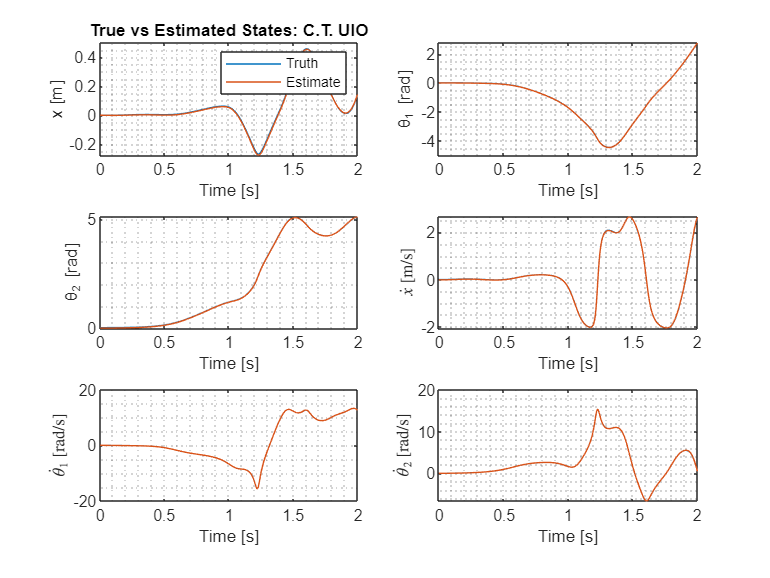

% State IC  [m, rad, rad, m/s, rad/s, rad/s]
x0      = [0 .01 .02 0 0 0]'; 

% UIO IC
z0      = zeros(6,1);

% Time interval and vector
dt          = .005;
time        = (0:dt:2)';

% ODE45 Function call
[T, X]      = ode45(@(t,x) DIPC_UIO(t, x, zeros(3,1), A, B1, C, D2, m1, m2, M, L1, L2, g, L_CT, M_CT), time, [x0;z0]);%, options);

% Initialize arrays
xhat        = zeros(length(z0),length(T));
ym          = zeros(length(C),length(T));
w           = zeros(length(ue),length(T));

% Propogate Estimates
for i = 1:length(T)
    [~, xhat(:,i),ym(:,i), w(:,i)]   = DIPC_UIO(T(i), X(i,:)', zeros(3,1), A, B1, C, D2, m1, m2, M, L1, L2, g, L_CT, M_CT);
end

figure
subplot(3,2,1)
plot(time,X(:,1), time, xhat(1,:))
title('True vs Estimated States: C.T. UIO')
legend('Truth','Estimate')
grid minor
ylabel('x [m]')
xlabel('Time [s]')
subplot(3,2,2)
plot(time,X(:,2), time, xhat(2,:))
grid minor
ylabel('\theta_1 [rad]')
xlabel('Time [s]')
subplot(3,2,3)
plot(time,X(:,3), time, xhat(3,:))
grid minor
ylabel('\theta_2 [rad]')
xlabel('Time [s]')
subplot(3,2,4)
plot(time,X(:,4), time, xhat(4,:))
grid minor
ylabel('$\dot{x}$ [m/s]','Interpreter','latex')
xlabel('Time [s]')
subplot(3,2,5)
plot(time,X(:,5), time, xhat(5,:))
grid minor
ylabel('$\dot{\theta}_1$ [rad/s]','Interpreter','latex')
xlabel('Time [s]')
subplot(3,2,6)
plot(time,X(:,6), time, xhat(6,:))
grid minor
ylabel('$\dot{\theta}_2$ [rad/s]','Interpreter','latex')
xlabel('Time [s]')

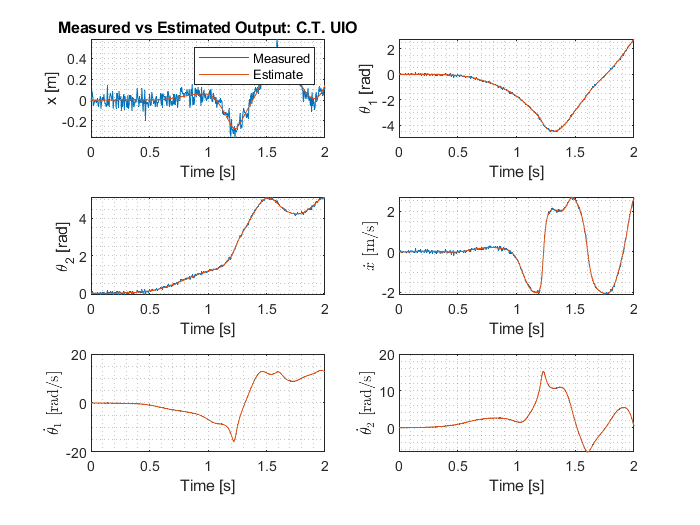

figure;
subplot(3,2,1)
plot(time,ym(1,:), time, xhat(1,:))
title('Measured vs Estimated Output: C.T. UIO')
legend('Measured','Estimate')
grid minor
ylabel('x [m]')
xlabel('Time [s]')
subplot(3,2,2)
plot(time,ym(2,:), time, xhat(2,:))
grid minor
ylabel('\theta_1 [rad]')
xlabel('Time [s]')
subplot(3,2,3)
plot(time,ym(3,:), time, xhat(3,:))
grid minor
ylabel('\theta_2 [rad]')
xlabel('Time [s]')
subplot(3,2,4)
plot(time,ym(4,:), time, xhat(4,:))
grid minor
ylabel('$\dot{x}$ [m/s]','Interpreter','latex')
xlabel('Time [s]')
subplot(3,2,5)
plot(time,ym(5,:), time, xhat(5,:))
grid minor
ylabel('$\dot{\theta}_1$ [rad/s]','Interpreter','latex')
xlabel('Time [s]')
subplot(3,2,6)
plot(time,ym(6,:), time, xhat(6,:))
grid minor
ylabel('$\dot{\theta}_2$ [rad/s]','Interpreter','latex')
xlabel('Time [s]')

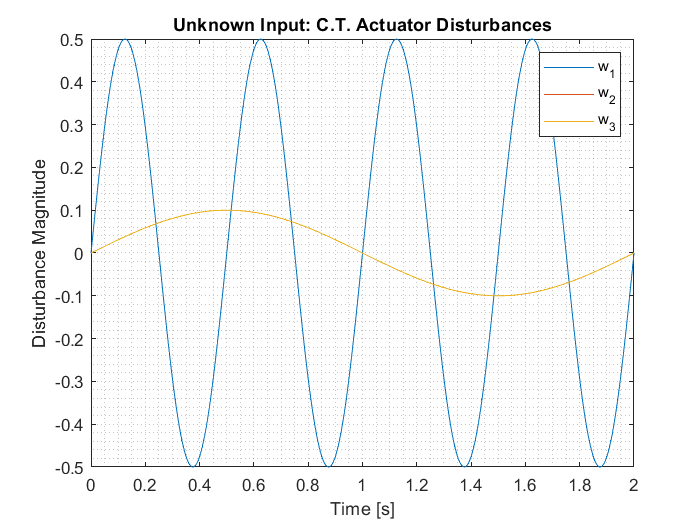

figure
plot(T, w)
xlabel('Time [s]')
grid minor
title('Unknown Input: C.T. Actuator Disturbances')
legend('w_1','w_2','w_3')
ylabel('Disturbance Magnitude')

## Problem 3 - D.T. Controller UIO Compensator

% Sampling Time - 50 Hz
Ts          = .02;

% New Initial Conditions
x0          = [.2 .2 .2 0 0 0]'; 

% New Observer IC
z0          = zeros(6,1);

% Discretize System
sysd        = c2d(ss(A,B1,C,D1),Ts);


$$x[k+1] = \Phi x[k] + \Gamma_1 u_1 + \Gamma_2 u_2\\
y[k] = Cx[x] + D_2u_3$$


phi         = sysd.A

phi =     1.0000   -0.0016    0.0000    0.0200   -0.0000    0.0000
         0    1.0131   -0.0059         0    0.0201   -0.0000
         0   -0.0066    1.0066         0   -0.0000    0.0200
         0   -0.1642    0.0003    1.0000   -0.0016    0.0000
         0    1.3150   -0.5925         0    1.0131   -0.0059
         0   -0.6583    0.6567         0   -0.0066    1.0066


gamma       = sysd.B

gamma =     0.0001   -0.0003    0.0000
   -0.0003    0.0021   -0.0011
    0.0000   -0.0011    0.0012
    0.0133   -0.0268    0.0001
   -0.0268    0.2145   -0.1074
    0.0001   -0.1074    0.1190


% Discrete Unknown Input Matrix
gamma2      = gamma

gamma2 =     0.0001   -0.0003    0.0000
   -0.0003    0.0021   -0.0011
    0.0000   -0.0011    0.0012
    0.0133   -0.0268    0.0001
   -0.0268    0.2145   -0.1074
    0.0001   -0.1074    0.1190


% Verify M exists and calculate
if rank([C*gamma2 D2]) == (rank(gamma2) + rank(D2))
    disp('D.T. Sufficiency condition met: M exists');

    % Moore-Penrose pseudo-invsere
    CB2D2_inv_DT = inv([C*gamma2 D2]'*[C*gamma2 D2])*[C*gamma2 D2]';

    % Calculate M
    M_DT         = [gamma2, zeros(n,r)]*CB2D2_inv_DT;
end

D.T. Sufficiency condition met: M exists


% check (I - M*C)B2 = 0 & M*D2 = 0
fprintf('\n')
disp('(I - MC)B2 = ')

(I - MC)B2 = 


disp(round((eye(n) - M_DT*C)*gamma2))

     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0



disp('M*D2 = ')

M*D2 = 


disp(round(M_DT*D2))

     0
     0
     0
     0
     0
     0



% Define A1
A1_DT       = (eye(n) - M_DT*C)*phi;

% Observability Matrix for pair (A1, C)
ob          = obsv(A1_DT,C);

% Check detectability
if rank(ob) == n
    disp('D.T. System is observable, & thus detectable')
end

D.T. System is observable, & thus detectable


% LMI to solve for D.T. observer gain
cvx_begin sdp quiet 
variable P(n,n) symmetric
variable Y(n,p)
[-P, A1_DT'*P-C'*Y'; P*A1_DT-Y*C, -P]<= 0
Y*D2 == 0
P >= eps*eye(n)
cvx_end

% Discrete observer gain
L_DT        = P\Y;

% UIO Poles
fprintf('\n')
disp('UIO D.T. Poles are')

UIO D.T. Poles are


disp(eig(A1_DT - L_DT*C))

   0.9916 + 0.0000i
  -0.8311 + 0.0000i
  -0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 - 0.0000i



% DARE Weight Matrices
Q           = 100*eye(n);
R           = .1*eye(length(ue));

% Number of inputs
m_u         = size(B1,2);

% LMI to solve DARE for K 
cvx_begin sdp quiet
variable S(n, n) symmetric
variable Z(m_u,n)
[-S, S, Z',Z'*gamma'-S*phi';...
S, -inv(Q), zeros(n,m_u), zeros(n,n);...
Z, zeros(m_u,n), -inv(R), zeros(m_u,n);...
gamma*Z-phi*S, zeros(n,n), zeros(n,m_u), -S] <= 0
S >= eps*eye(n)
cvx_end

% D.T. Controller Gain
K_DT        = Z/S;

% System Closed Loop Poles eig(A-BK)
fprintf('\n')
disp('Closed Loop D.T. Poles are')

Closed Loop D.T. Poles are


disp(eig(phi - gamma*K_DT))

    0.0057
    0.1558
    0.5643
    0.9278
    0.9658
    0.9741



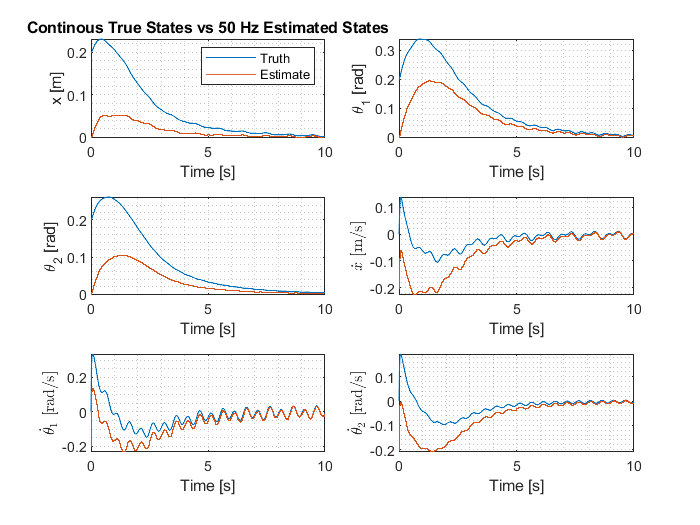

sim_out      = sim('HW5_model.slx');

% Extract Simulink Signals
x_ct         = sim_out.logsout{1}.Values.Data(:,:);
t_ct         = sim_out.logsout{1}.Values.Time;
xhat_DT      = sim_out.logsout{3}.Values.Data(:,:);
t_50Hz       = sim_out.logsout{3}.Values.Time;
ym_DT        = sim_out.logsout{6}.Values.Data(:,:);
u_DT         = sim_out.logsout{4}.Values.Data(:,:);
w_DT         = sim_out.logsout{5}.Values.Data(:,:);

figure
subplot(3,2,1)
plot(t_ct,x_ct(1,:))
title('Continous True States vs 50 Hz Estimated States')
hold on
stairs(t_50Hz, xhat_DT(1,:))
hold off
legend('Truth','Estimate')
grid minor
ylabel('x [m]')
xlabel('Time [s]')
subplot(3,2,2)
plot(t_ct,x_ct(2,:))
hold on
stairs(t_50Hz, xhat_DT(2,:))
hold off
grid minor
ylabel('\theta_1 [rad]')
xlabel('Time [s]')
subplot(3,2,3)
plot(t_ct,x_ct(3,:))
hold on
stairs(t_50Hz, xhat_DT(3,:))
hold off
grid minor
ylabel('\theta_2 [rad]')
xlabel('Time [s]')
subplot(3,2,4)
plot(t_ct,x_ct(4,:))
hold on
stairs(t_50Hz, xhat_DT(4,:))
hold off
grid minor
ylabel('$\dot{x}$ [m/s]','Interpreter','latex')
xlabel('Time [s]')
subplot(3,2,5)
plot(t_ct,x_ct(5,:))
hold on
stairs(t_50Hz, xhat_DT(5,:))
hold off
grid minor
ylabel('$\dot{\theta}_1$ [rad/s]','Interpreter','latex')
xlabel('Time [s]')
subplot(3,2,6)
plot(t_ct,x_ct(6,:))
hold on
stairs(t_50Hz, xhat_DT(6,:))
hold off
grid minor
ylabel('$\dot{\theta}_2$ [rad/s]','Interpreter','latex')
xlabel('Time [s]')

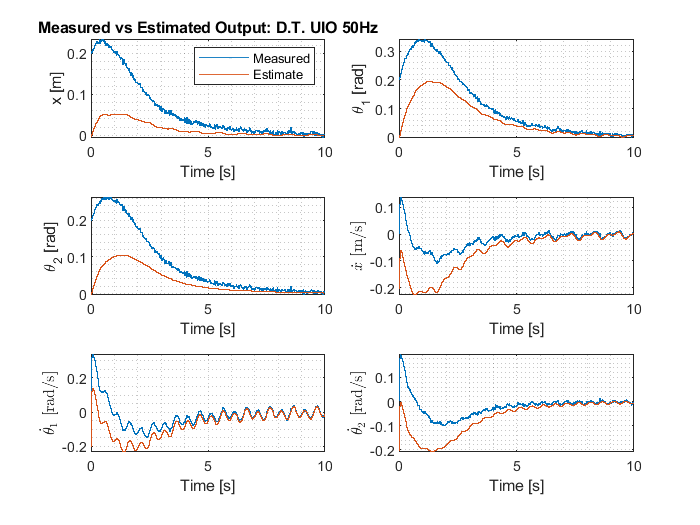

figure
subplot(3,2,1)
stairs(t_50Hz,ym_DT(1,:))
hold on
title('Measured vs Estimated Output: D.T. UIO 50Hz')
stairs(t_50Hz, xhat_DT(1,:))
hold off
legend('Measured','Estimate')
grid minor
ylabel('x [m]')
xlabel('Time [s]')
subplot(3,2,2)
stairs(t_50Hz,ym_DT(2,:))
hold on
stairs(t_50Hz, xhat_DT(2,:))
hold off
grid minor
ylabel('\theta_1 [rad]')
xlabel('Time [s]')
subplot(3,2,3)
stairs(t_50Hz,ym_DT(3,:))
hold on
stairs(t_50Hz, xhat_DT(3,:))
hold off
grid minor
ylabel('\theta_2 [rad]')
xlabel('Time [s]')
subplot(3,2,4)
stairs(t_50Hz,ym_DT(4,:))
hold on
stairs(t_50Hz, xhat_DT(4,:))
hold off
grid minor
ylabel('$\dot{x}$ [m/s]','Interpreter','latex')
xlabel('Time [s]')
subplot(3,2,5)
stairs(t_50Hz,ym_DT(5,:))
hold on
stairs(t_50Hz, xhat_DT(5,:))
hold off
grid minor
ylabel('$\dot{\theta}_1$ [rad/s]','Interpreter','latex')
xlabel('Time [s]')
subplot(3,2,6)
stairs(t_50Hz,ym_DT(6,:))
hold on
stairs(t_50Hz, xhat_DT(6,:))
hold off
grid minor
ylabel('$\dot{\theta}_2$ [rad/s]','Interpreter','latex')
xlabel('Time [s]')

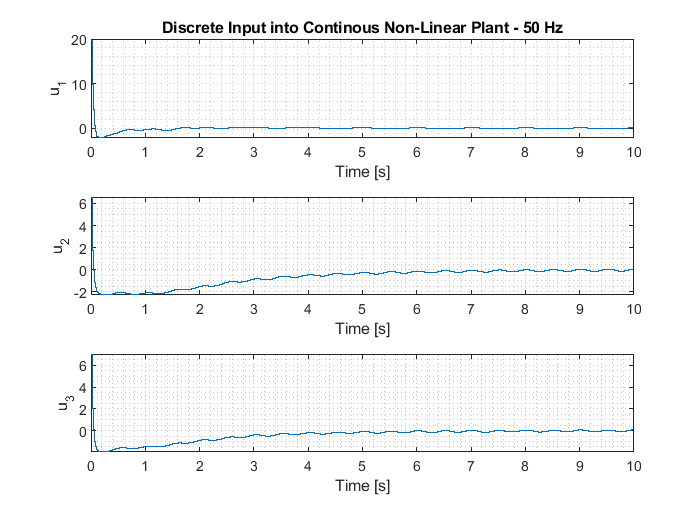

figure
subplot(311)
stairs(t_50Hz, u_DT(1,:))
xlabel('Time [s]')
ylabel('u_1')
grid minor
title('Discrete Input into Continous Non-Linear Plant - 50 Hz')
subplot(312)
stairs(t_50Hz, u_DT(2,:))
xlabel('Time [s]')
ylabel('u_2')
grid minor
subplot(313)
stairs(t_50Hz, u_DT(3,:))
xlabel('Time [s]')
ylabel('u_3')
grid minor

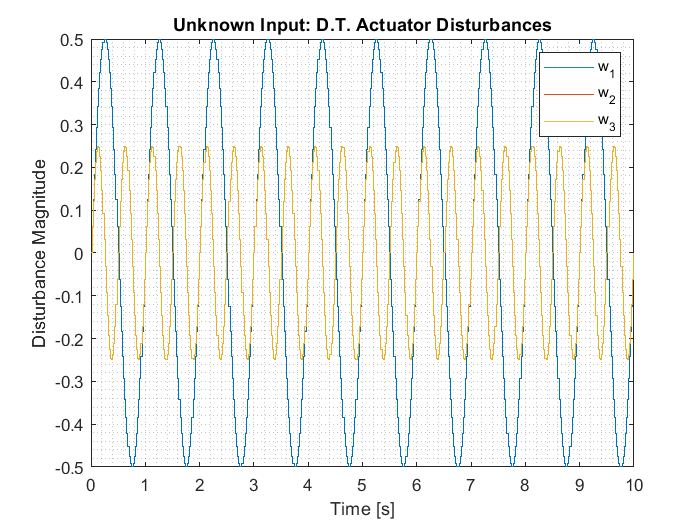

figure
stairs(t_50Hz, w_DT)
xlabel('Time [s]')
grid minor
title('Unknown Input: D.T. Actuator Disturbances')
legend('w_1','w_2','w_3')
ylabel('Disturbance Magnitude')

## Functions

function xdot = DIPC(t, x, u, m1, m2, M, L1, L2, g)

% Define State and Input Vectors
x1          = x(1,1);  % x
x2          = x(2,1);  % theta_1
x3          = x(3,1);  % theta_2
x4          = x(4,1);  % xdot
x5          = x(5,1);  % theta_1_dot
x6          = x(6,1);  % theta_2_dot
u1          = u(1,1);
u2          = u(2,1);
u3          = u(3,1);

% State Dynamics
x1dot       = x4;   % xdot
x2dot       = x5;   % theta_1_dot
x3dot       = x6;   % theta_2_dot

% x_ddot
x4dot       = (L2*m2*u2*cos(x2 - 2*x3) - L1*m1*u3*cos(x3) - L2*m2*u2*cos(x2)...
               - L1*m2*u3*cos(x3) - 2*L2*m1*u2*cos(x2) + 2*L1*L2*m1*u1 + L1*L2*m2*u1...
               + L1*m1*u3*cos(2*x2 - x3) + L1*m2*u3*cos(2*x2 - x3) -...
               L1*L2*m2*u1*cos(2*x2 - 2*x3) - L1*L2*g*m1^2*sin(2*x2) +...
               2*L1^2*L2*m1^2*x5^2*sin(x2) - L1*L2*g*m1*m2*sin(2*x2) +...
               L1*L2^2*m1*m2*x6^2*sin(2*x2 - x3) + 2*L1^2*L2*m1*m2*x5^2*sin(x2) +...
               L1*L2^2*m1*m2*x6^2*sin(x3))/(L1*L2*(2*M*m1 + M*m2 + m1*m2 -...
               m1^2*cos(2*x2) + m1^2 - m1*m2*cos(2*x2) - M*m2*cos(2*x2 - 2*x3)));
 
% theta_1_ddot
x5dot       = -(L2*m2*u2*cos(2*x3) - 2*L2*m1*u2 - L2*m2*u2 - 2*L2*M*u2 -...
                2*L1*L2*g*m1^2*sin(x2) + 2*L1*M*u3*cos(x2)*cos(x3) +...
                2*L1*M*u3*sin(x2)*sin(x3) + L1^2*L2*m1^2*x5^2*sin(2*x2) +...
                2*L1*m1*u3*sin(x2)*sin(x3) + 2*L1*m2*u3*sin(x2)*sin(x3) +...
                2*L1*L2*m1*u1*cos(x2) + L1*L2*m2*u1*cos(x2) - 2*L1*L2*M*g*m1*sin(x2)...
                - L1*L2*M*g*m2*sin(x2) - L1*L2*m2*u1*sin(2*x3)*sin(x2) -...
                2*L1*L2*g*m1*m2*sin(x2) + L1^2*L2*m1*m2*x5^2*sin(2*x2) -...
                L1*L2*m2*u1*cos(2*x3)*cos(x2) - L1*L2*M*g*m2*cos(2*x3)*sin(x2) +...
                L1*L2*M*g*m2*sin(2*x3)*cos(x2) - L1^2*L2*M*m2*x5^2*cos(2*x2)*sin(2*x3) +...
                L1^2*L2*M*m2*x5^2*cos(2*x3)*sin(2*x2) - 2*L1*L2^2*M*m2*x6^2*cos(x2)*sin(x3) +...
                2*L1*L2^2*M*m2*x6^2*cos(x3)*sin(x2) + 2*L1*L2^2*m1*m2*x6^2*cos(x3)*sin(x2))/...
                (L1^2*L2*(2*M*m1 + M*m2 + m1*m2 - m1^2*cos(2*x2) + m1^2 -...
                m1*m2*cos(2*x2) - M*m2*cos(2*x2 - 2*x3)));


% theta_2_ddot
x6dot       = (L1*m1^2*u3 + L1*m2^2*u3 - L1*m1^2*u3*cos(2*x2) - L1*m2^2*u3*cos(2*x2) +...
              L2*m2^2*u2*cos(x2 + x3) + 2*L1*M*m1*u3 + 2*L1*M*m2*u3 + 2*L1*m1*m2*u3 -...
              L2*m2^2*u2*cos(x2 - x3) - L2*m1*m2*u2*cos(x2 - x3) - L1*L2*m2^2*u1*cos(x3) -...
              2*L1*m1*m2*u3*cos(2*x2) + L1*L2*m2^2*u1*cos(2*x2 - x3) +...
              L2*m1*m2*u2*cos(x2 + x3) - 2*L2*M*m2*u2*cos(x2 - x3) - L1*L2*m1*m2*u1*cos(x3) +...
              L1*L2*M*g*m2^2*sin(x3) + 2*L1^2*L2*M*m2^2*x5^2*sin(x2 - x3) +...
              L1*L2*m1*m2*u1*cos(2*x2 - x3) + L1*L2^2*M*m2^2*x6^2*sin(2*x2 - 2*x3) -...
              L1*L2*M*g*m2^2*sin(2*x2 - x3) - L1*L2*M*g*m1*m2*sin(2*x2 - x3) +...
              L1*L2*M*g*m1*m2*sin(x3) + 2*L1^2*L2*M*m1*m2*x5^2*sin(x2 - x3))/...
              (L1*L2^2*m2*(2*M*m1 + M*m2 + m1*m2 - m1^2*cos(2*x2) + m1^2 -...
              m1*m2*cos(2*x2) - M*m2*cos(2*x2 - 2*x3)));


xdot        = [x1dot;x2dot;x3dot;x4dot;x5dot;x6dot];
end

function [xdot, xhat, ym, w] = DIPC_UIO(t, x, u, A, B1, C, D2, m1, m2, M, L1, L2, g, L, M_UIO)

% Define State and Input Vectors
x1          = x(1,1);       % x
x2          = x(2,1);       % theta_1
x3          = x(3,1);       % theta_2
x4          = x(4,1);       % xdot
x5          = x(5,1);       % theta_1_dot
x6          = x(6,1);       % theta_2_dot
z           = x(7:end,1);   % UIO States

% Outputs
y           = C*x(1:6,1);

% Sensor Attacks - noise applied to each sensor
v           = .05*randn(1);

% Measured Ouput
ym          = y + D2*v;

% Distrubances -  Actuator Attacks
w1          = .5*sin(4*pi*t);
w2          = .1*sin(pi*t);
w3          =  w2;
w           = [w1;w2;w3];
u1          = u(1,1) + w1;
u2          = u(2,1) + w2;
u3          = u(3,1) + w3;


% State Dynamics
x1dot       = x4;   % xdot
x2dot       = x5;   % theta_1_dot
x3dot       = x6;   % theta_2_dot

% State Estimates
xhat        = z + M_UIO*ym;

% Estimated Output
yhat        = C*xhat;

% x_ddot
x4dot       = (L2*m2*u2*cos(x2 - 2*x3) - L1*m1*u3*cos(x3) - L2*m2*u2*cos(x2)...
               - L1*m2*u3*cos(x3) - 2*L2*m1*u2*cos(x2) + 2*L1*L2*m1*u1 + L1*L2*m2*u1...
               + L1*m1*u3*cos(2*x2 - x3) + L1*m2*u3*cos(2*x2 - x3) -...
               L1*L2*m2*u1*cos(2*x2 - 2*x3) - L1*L2*g*m1^2*sin(2*x2) +...
               2*L1^2*L2*m1^2*x5^2*sin(x2) - L1*L2*g*m1*m2*sin(2*x2) +...
               L1*L2^2*m1*m2*x6^2*sin(2*x2 - x3) + 2*L1^2*L2*m1*m2*x5^2*sin(x2) +...
               L1*L2^2*m1*m2*x6^2*sin(x3))/(L1*L2*(2*M*m1 + M*m2 + m1*m2 -...
               m1^2*cos(2*x2) + m1^2 - m1*m2*cos(2*x2) - M*m2*cos(2*x2 - 2*x3)));
 
% theta_1_ddot
x5dot       = -(L2*m2*u2*cos(2*x3) - 2*L2*m1*u2 - L2*m2*u2 - 2*L2*M*u2 -...
                2*L1*L2*g*m1^2*sin(x2) + 2*L1*M*u3*cos(x2)*cos(x3) +...
                2*L1*M*u3*sin(x2)*sin(x3) + L1^2*L2*m1^2*x5^2*sin(2*x2) +...
                2*L1*m1*u3*sin(x2)*sin(x3) + 2*L1*m2*u3*sin(x2)*sin(x3) +...
                2*L1*L2*m1*u1*cos(x2) + L1*L2*m2*u1*cos(x2) - 2*L1*L2*M*g*m1*sin(x2)...
                - L1*L2*M*g*m2*sin(x2) - L1*L2*m2*u1*sin(2*x3)*sin(x2) -...
                2*L1*L2*g*m1*m2*sin(x2) + L1^2*L2*m1*m2*x5^2*sin(2*x2) -...
                L1*L2*m2*u1*cos(2*x3)*cos(x2) - L1*L2*M*g*m2*cos(2*x3)*sin(x2) +...
                L1*L2*M*g*m2*sin(2*x3)*cos(x2) - L1^2*L2*M*m2*x5^2*cos(2*x2)*sin(2*x3) +...
                L1^2*L2*M*m2*x5^2*cos(2*x3)*sin(2*x2) - 2*L1*L2^2*M*m2*x6^2*cos(x2)*sin(x3) +...
                2*L1*L2^2*M*m2*x6^2*cos(x3)*sin(x2) + 2*L1*L2^2*m1*m2*x6^2*cos(x3)*sin(x2))/...
                (L1^2*L2*(2*M*m1 + M*m2 + m1*m2 - m1^2*cos(2*x2) + m1^2 -...
                m1*m2*cos(2*x2) - M*m2*cos(2*x2 - 2*x3)));


% theta_2_ddot
x6dot       = (L1*m1^2*u3 + L1*m2^2*u3 - L1*m1^2*u3*cos(2*x2) - L1*m2^2*u3*cos(2*x2) +...
              L2*m2^2*u2*cos(x2 + x3) + 2*L1*M*m1*u3 + 2*L1*M*m2*u3 + 2*L1*m1*m2*u3 -...
              L2*m2^2*u2*cos(x2 - x3) - L2*m1*m2*u2*cos(x2 - x3) - L1*L2*m2^2*u1*cos(x3) -...
              2*L1*m1*m2*u3*cos(2*x2) + L1*L2*m2^2*u1*cos(2*x2 - x3) +...
              L2*m1*m2*u2*cos(x2 + x3) - 2*L2*M*m2*u2*cos(x2 - x3) - L1*L2*m1*m2*u1*cos(x3) +...
              L1*L2*M*g*m2^2*sin(x3) + 2*L1^2*L2*M*m2^2*x5^2*sin(x2 - x3) +...
              L1*L2*m1*m2*u1*cos(2*x2 - x3) + L1*L2^2*M*m2^2*x6^2*sin(2*x2 - 2*x3) -...
              L1*L2*M*g*m2^2*sin(2*x2 - x3) - L1*L2*M*g*m1*m2*sin(2*x2 - x3) +...
              L1*L2*M*g*m1*m2*sin(x3) + 2*L1^2*L2*M*m1*m2*x5^2*sin(x2 - x3))/...
              (L1*L2^2*m2*(2*M*m1 + M*m2 + m1*m2 - m1^2*cos(2*x2) + m1^2 -...
              m1*m2*cos(2*x2) - M*m2*cos(2*x2 - 2*x3)));

% UIO Dynamics
zdot        = (eye(size(M_UIO*C)) - M_UIO*C)*(A*z + A*M_UIO*ym + B1*u) + L*(ym - yhat);


xdot        = [x1dot;x2dot;x3dot;x4dot;x5dot;x6dot;zdot];
end
